clear; close all;

R1 = 100e3;   C1 = 0.1e-6;
R2 = 47e3;    C2 = 0.1e-6;
tau1 = R1*C1;                      
tau2 = R2*C2;                      

s = tf('s');
G = 1/((tau1*s + 1)*(tau2*s + 1))


G =
 
              1
  --------------------------
  4.7e-05 s^2 + 0.0147 s + 1
 
Continuous-time transfer function.


PO_max = 5;                     
Ts_max = 0.1;                    

zeta_min  = -log(PO_max/100)/sqrt(pi^2 + log(PO_max/100)^2);
sigma_min = 4/Ts_max;
fprintf('Región de diseño: zeta >= %.4f y zeta*wn >= %.0f 1/s\n', zeta_min, sigma_min);

Región de diseño: zeta >= 0.6901 y zeta*wn >= 40 1/s


%% 1. Lugar de raíces de kp*G(s) y elección de kp
k_vec = [linspace(0, 0.2, 400), linspace(0.2, 20, 2000)];
r = rlocus(G, k_vec);

sigma_P = -(tau1 + tau2)/(2*tau1*tau2);            
kp_ruptura = ((tau1 + tau2)/2)^2/(tau1*tau2) - 1;

theta  = acos(zeta_min);                       
s_star = sigma_P + 1j*abs(sigma_P)*tan(theta);

kp_modulo  = 1/abs(evalfr(G, s_star));                         
kp_formula = ((tau1 + tau2)/(2*zeta_min))^2/(tau1*tau2) - 1;    
fprintf('Parte real de los polos complejos: %.1f 1/s -> Ts se cumple para cualquier kp\n', sigma_P);

Parte real de los polos complejos: -156.4 1/s -> Ts se cumple para cualquier kp


fprintf('kp de ruptura (las ramas se juntan): %.4f\n', kp_ruptura);

kp de ruptura (las ramas se juntan): 0.1494


fprintf('Polo deseado: s* = %.1f %+.1fj\n', real(s_star), imag(s_star));

Polo deseado: s* = -156.4 +164.0j


fprintf('kp máximo para PO <= 5 %%: criterio del módulo = %.4f | fórmula de zeta = %.4f\n', kp_modulo, kp_formula);

kp máximo para PO <= 5 %: criterio del módulo = 1.4135 | fórmula de zeta = 1.4135


kp_max = kp_formula;

[~, zeta_P] = damp(feedback(kp_max*G, 1));
fprintf('Chequeo: zeta del lazo cerrado = %.4f (esperado %.4f)\n', zeta_P(1), zeta_min);

Chequeo: zeta del lazo cerrado = 0.6901 (esperado 0.6901)


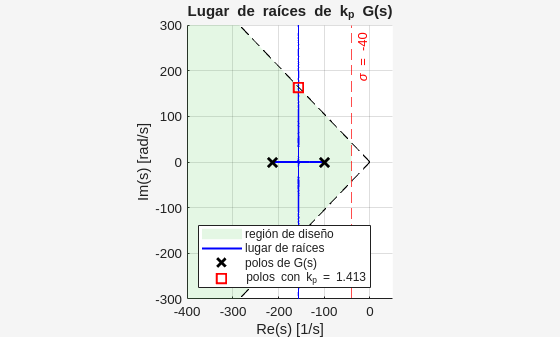

% Gráfico: lugar de raíces sobre la región donde deben quedar los polos
x_izq = -400;
tn = tan(theta);
figure
hold on
hr = patch([-sigma_min x_izq x_izq -sigma_min], [sigma_min*tn -x_izq*tn x_izq*tn -sigma_min*tn], [0.3 0.8 0.3], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
hl = plot(real(r).', imag(r).', 'b', 'LineWidth', 1.5);
hx = plot([-1/tau1 -1/tau2], [0 0], 'kx', 'MarkerSize', 10, 'LineWidth', 2);
plot([0 x_izq], [0 -x_izq*tn], 'k--', [0 x_izq], [0 x_izq*tn], 'k--');
xline(-sigma_min, 'r--', '\sigma = -40');
r_kp = rlocus(G, kp_max);
hs = plot(real(r_kp), imag(r_kp), 'rs', 'MarkerSize', 9, 'LineWidth', 2);
grid on; axis equal
xlim([x_izq 50]); ylim([-300 300])
xlabel('Re(s) [1/s]'); ylabel('Im(s) [rad/s]')
legend([hr, hl(1), hx, hs], {'región de diseño', 'lugar de raíces', 'polos de G(s)', sprintf('polos con k_p = %.3f', kp_max)}, 'Location', 'southwest')
title('Lugar de raíces de k_p G(s)')
guardar("TP2_P1_lugar_raices")

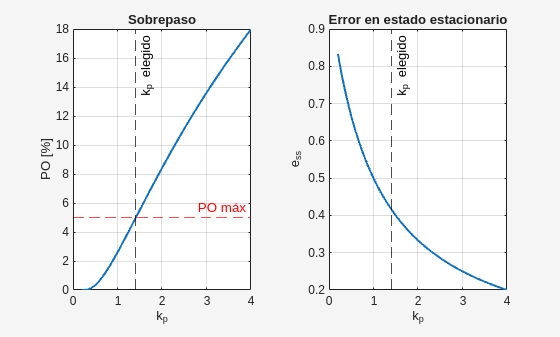

kp_b   = linspace(0.2, 4, 300);
zeta_b = (tau1 + tau2)./(2*sqrt(tau1*tau2*(1 + kp_b)));
figure
tiledlayout(1, 2)
nexttile
plot(kp_b, 100*exp(-pi*zeta_b./sqrt(1 - zeta_b.^2)), 'LineWidth', 1.5); hold on
yline(PO_max, 'r--', 'PO máx'); xline(kp_max, 'k--', 'k_p elegido');
grid on; xlabel('k_p'); ylabel('PO [%]'); title('Sobrepaso')
nexttile
plot(kp_b, 1./(1 + kp_b), 'LineWidth', 1.5); hold on
xline(kp_max, 'k--', 'k_p elegido');
grid on; xlabel('k_p'); ylabel('e_{ss}'); title('Error en estado estacionario')
guardar("TP2_P1_compromiso")

%% 2. Verificación con la respuesta al escalón
kp  = kp_max;
T_P = feedback(kp*G, 1);
t   = (0:1e-5:0.12)';        
y   = step(T_P, t);
info = stepinfo(y, t);       
ess  = 1 - y(end);            

fprintf('ess simulado = %.4f | teórico 1/(1+kp) = %.4f\n', ess, 1/(1 + kp));

ess simulado = 0.4143 | teórico 1/(1+kp) = 0.4143


cumple = [info.Overshoot <= PO_max + 0.01; info.SettlingTime <= Ts_max; abs(ess) < 1e-3];
T_spec = table(["PO [%]"; "Ts [ms]"; "ess"], [info.Overshoot; info.SettlingTime*1e3; ess], ["<= 5"; "<= 100"; "= 0"], cumple, 'VariableNames', {'Parametro', 'Valor', 'Especificacion', 'Cumple'})

T_spec = 3×4 table
    Parametro     Valor     Especificacion    Cumple
    _________    _______    ______________    ______

    "PO [%]"           5       "<= 5"         true  
    "Ts [ms]"     26.457       "<= 100"       true  
    "ess"        0.41434       "= 0"          false 


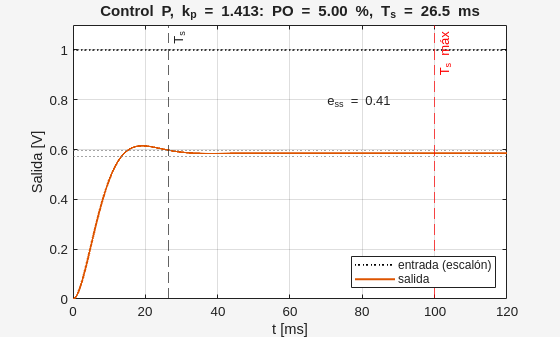

figure
plot(t*1e3, ones(size(t)), 'k:', 'LineWidth', 1.2); hold on
plot(t*1e3, y, 'LineWidth', 1.5)
yline(y(end)*[0.98 1.02], ':', 'Color', [0.5 0.5 0.5]);
xline(info.SettlingTime*1e3, '--', 'T_s');
xline(Ts_max*1e3, 'r--', 'T_s máx');
text(70, (1 + y(end))/2, sprintf('e_{ss} = %.2f', ess))
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); ylim([0 1.1])
legend('entrada (escalón)', 'salida', 'Location', 'southeast')
title(sprintf('Control P, k_p = %.3f: PO = %.2f %%, T_s = %.1f ms', kp, info.Overshoot, info.SettlingTime*1e3))
guardar("TP2_P2_escalon")

%% 3. Valores comerciales de serie E24
E24 = [1.0 1.1 1.2 1.3 1.5 1.6 1.8 2.0 2.2 2.4 2.7 3.0 3.3 3.6 3.9 4.3 4.7 5.1 5.6 6.2 6.8 7.5 8.2 9.1];
valores = [E24*1e3, E24*1e4, 100e3];  

[R7_g, R9_g] = meshgrid(valores, valores);
kp_g = 1 + R7_g./R9_g;

distancia = kp_max - kp_g;
distancia(distancia < 0) = Inf;
[~, orden] = sort(distancia(:));
mejores = orden(1:6);
T_E24 = table(R7_g(mejores)/1e3, R9_g(mejores)/1e3, kp_g(mejores), 'VariableNames', {'R7_kOhm', 'R9_kOhm', 'kp'})

T_E24 = 6×3 table
    R7_kOhm    R9_kOhm      kp  
    _______    _______    ______

      6.2         15      1.4133
      1.6        3.9      1.4103
       16         39      1.4103
      8.2         20        1.41
      1.1        2.7      1.4074
       11         27      1.4074


R7 = 6.2e3;
R9 = 15e3;
kp_c = 1 + R7/R9;
fprintf('kp comercial = %.5f (error relativo respecto de kp_max: %.4f %%)\n', kp_c, 100*(kp_c - kp_max)/kp_max);

kp comercial = 1.41333 (error relativo respecto de kp_max: -0.0106 %)


y_c = step(feedback(kp_c*G, 1), t);
info_c = stepinfo(y_c, t);
ess_c = 1 - y_c(end);

zeta_c = (tau1 + tau2)/(2*sqrt(tau1*tau2*(1 + kp_c)));
fprintf('PO simulado = %.4f %% | fórmula = %.4f %%\n', info_c.Overshoot, 100*exp(-pi*zeta_c/sqrt(1 - zeta_c^2)));

PO simulado = 4.9991 % | fórmula = 4.9991 %


T_P3 = table(["kp"; "PO [%]"; "Ts [ms]"; "ess"], [kp_max; info.Overshoot; info.SettlingTime*1e3; ess], [kp_c; info_c.Overshoot; info_c.SettlingTime*1e3; ess_c], 'VariableNames', {'Parametro', 'Diseno', 'Comercial'})

T_P3 = 4×3 table
    Parametro    Diseno     Comercial
    _________    _______    _________

    "kp"          1.4135      1.4133 
    "PO [%]"           5      4.9991 
    "Ts [ms]"     26.457      26.457 
    "ess"        0.41434     0.41436 


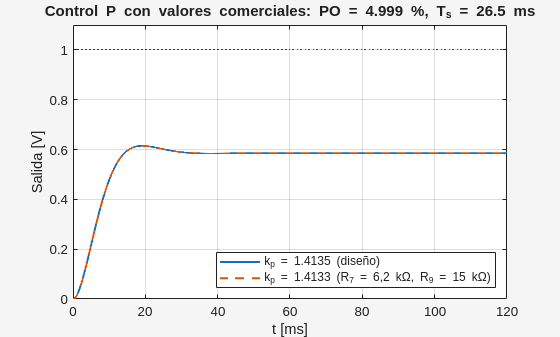

figure
plot(t*1e3, y, 'LineWidth', 1.5); hold on
plot(t*1e3, y_c, '--', 'LineWidth', 1.5)
yline(1, 'k:');
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); ylim([0 1.1])
legend(sprintf('k_p = %.4f (diseño)', kp_max), sprintf('k_p = %.4f (R_7 = 6,2 k\\Omega, R_9 = 15 k\\Omega)', kp_c), 'Location', 'southeast')
title(sprintf('Control P con valores comerciales: PO = %.3f %%, T_s = %.1f ms', info_c.Overshoot, info_c.SettlingTime*1e3))
guardar("TP2_P3_E24")

%% 4. Simulación circuital del lazo P con TL081
R3 = 1e3;  R4 = 1e3;  R5 = 1e3;  R6 = 1e3;  R8 = 1e3;
R7 = 6.2e3;  R9 = 15e3;                   
R10 = 1e3;
Vin = 1;                                

modelo_P = 'lazo_P';
load_system(modelo_P)
out_P = sim(modelo_P, 'StopTime', '0.12');

[t_s, iu] = unique(out_P.y_sim.Time);
y_s = squeeze(out_P.y_sim.Data);
y_s = y_s(iu);
y_sc = interp1(t_s, y_s, t);

y_ft = Vin*step(feedback(kp_c*G, 1), t);

err_P   = max(abs(y_sc - y_ft));
info_ft = stepinfo(y_ft, t);
info_sc = stepinfo(y_sc, t);
ess_ft  = Vin - y_ft(end);
ess_sc  = Vin - y_sc(end);

A0 = 2e5;
L0 = (A0/(A0 + 2))*(A0/(A0 + 1))*(kp_c*A0/(kp_c + A0));
fprintf('y(final): Simscape = %.6f | teórico con A0 finita = %.6f | ideal = %.6f\n', y_sc(end), L0/(1 + L0), kp_c/(1 + kp_c));

y(final): Simscape = 0.585630 | teórico con A0 finita = 0.585630 | ideal = 0.585635


fprintf('Error máximo |y_Simscape - y_FT| = %.2e V\n', err_P);

Error máximo |y_Simscape - y_FT| = 1.72e-05 V



T_P4 = table(["PO [%]"; "Ts [ms]"; "ess"], [info_ft.Overshoot; info_ft.SettlingTime*1e3; ess_ft], [info_sc.Overshoot; info_sc.SettlingTime*1e3; ess_sc], 'VariableNames', {'Parametro', 'Modelo_FT', 'Simscape_TL081'})

T_P4 = 3×3 table
    Parametro    Modelo_FT    Simscape_TL081
    _________    _________    ______________

    "PO [%]"       4.9991         4.9996    
    "Ts [ms]"      26.457         26.458    
    "ess"         0.41436        0.41437    


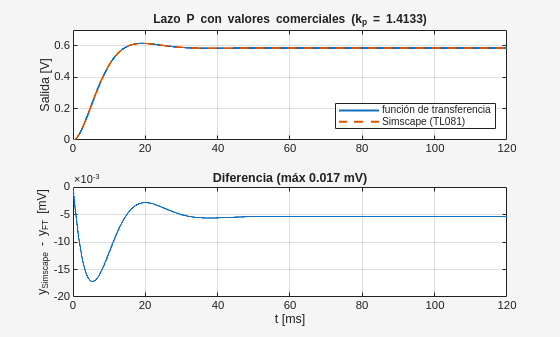


figure
tiledlayout(2, 1)
nexttile
plot(t*1e3, y_ft, 'LineWidth', 1.5); hold on
plot(t*1e3, y_sc, '--', 'LineWidth', 1.5)
grid on; ylabel('Salida [V]'); ylim([0 0.7])
legend('función de transferencia', 'Simscape (TL081)', 'Location', 'southeast')
title(sprintf('Lazo P con valores comerciales (k_p = %.4f)', kp_c))
nexttile
plot(t*1e3, (y_sc - y_ft)*1e3, 'LineWidth', 1.2)
grid on; xlabel('t [ms]'); ylabel('y_{Simscape} - y_{FT} [mV]')
title(sprintf('Diferencia (máx %.3f mV)', err_P*1e3))
guardar("TP2_P4_simscape")

%% Segunda parte: control PI
a3 = tau1*tau2;
a2 = tau1 + tau2;
fprintf('Estable si: ki > 0 y ki < %.2f (1 + kp)   (de ahí también kp > -1)\n', a2/a3);

Estable si: ki > 0 y ki < 312.77 (1 + kp)   (de ahí también kp > -1)


kp_grid = linspace(-2, 4, 121);
ki_grid = linspace(-200, 1600, 181);
estable = false(numel(ki_grid), numel(kp_grid));
for i = 1:numel(ki_grid)
    for j = 1:numel(kp_grid)
        raices = roots([a3, a2, 1 + kp_grid(j), ki_grid(i)]);
        estable(i, j) = all(real(raices) < 0);
    end
end
routh = (ki_grid' > 0) & (ki_grid' < a2/a3*(1 + kp_grid));
fprintf('Puntos de la grilla donde Routh y las raíces no coinciden: %d de %d\n', nnz(estable ~= routh), numel(estable));

Puntos de la grilla donde Routh y las raíces no coinciden: 0 de 21901


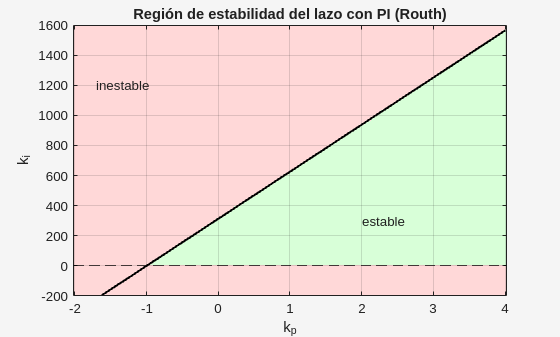


figure
imagesc(kp_grid, ki_grid, estable); axis xy; hold on
colormap([1 0.85 0.85; 0.85 1 0.85])
plot(kp_grid, a2/a3*(1 + kp_grid), 'k', 'LineWidth', 1.5)
yline(0, 'k--');
text(2, 300, 'estable'); text(-1.7, 1200, 'inestable')
grid on; xlabel('k_p'); ylabel('k_i'); ylim([-200 1600])
title('Región de estabilidad del lazo con PI (Routh)')
guardar("TP2_PI1_routh")

fprintf('zeta >= %.4f -> ángulo máximo de %.1f° respecto del semieje real negativo\n', zeta_min, acosd(zeta_min));

zeta >= 0.6901 -> ángulo máximo de 46.4° respecto del semieje real negativo


fprintf('zeta*wn >= %.0f -> polos a la izquierda de sigma = -%.0f\n', sigma_min, sigma_min);

zeta*wn >= 40 -> polos a la izquierda de sigma = -40


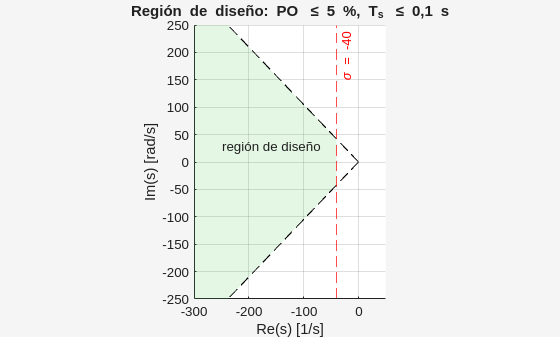

figure
dibujar_region(zeta_min, sigma_min, -300, 250)
text(-250, 30, 'región de diseño')
title('Región de diseño: PO \leq 5 %, T_s \leq 0,1 s')
guardar("TP2_PI2a_region")

%% PI-2b. 
suma_polos = 0 - 1/tau1 - 1/tau2;
sigma_a = @(z) (suma_polos + z)/2;
z_lim = -2*sigma_min - suma_polos;       
fprintf('sigma_a(z) = (z - %.2f)/2 ; asíntotas a la izquierda de -40 si z < %.2f\n', -suma_polos, z_lim);

sigma_a(z) = (z - 312.77)/2 ; asíntotas a la izquierda de -40 si z < 232.77



z_prueba = 100;
kp_grande = 1e4;
raices = roots([a3, a2, 1 + kp_grande, kp_grande*z_prueba]);
fprintf('z = %d: sigma_a = %.2f | parte real de los polos complejos con kp = 1e4: %.2f\n', z_prueba, sigma_a(z_prueba), mean(real(raices(abs(imag(raices)) > 1e-6))));

z = 100: sigma_a = -106.38 | parte real de los polos complejos con kp = 1e4: -106.38


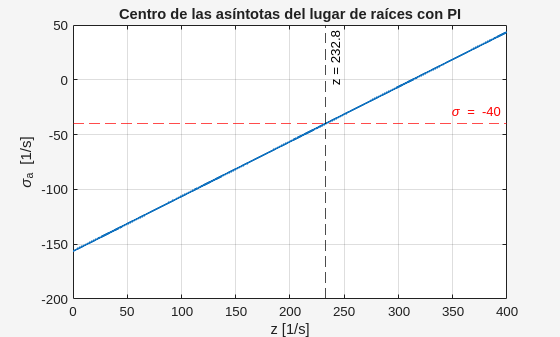


z_vec = linspace(0, 400, 401);
figure
plot(z_vec, sigma_a(z_vec), 'LineWidth', 1.5); hold on
yline(-sigma_min, 'r--', '\sigma = -40');
xline(z_lim, 'k--', sprintf('z = %.1f', z_lim));
grid on; xlabel('z [1/s]'); ylabel('\sigma_a [1/s]')
title('Centro de las asíntotas del lugar de raíces con PI')
guardar("TP2_PI2b_asintotas")

%% 2c. Elección del cero z del PI
zeta_d = 0.69;                 % lo que pide la guía
a3 = tau1*tau2;
a2 = tau1 + tau2;
sP = -156.385 + 164.0j;       

z_prueba = [30 35 40 45 50 55 60 80 100];
t_largo  = (0:1e-5:1)';
kp_z = zeros(size(z_prueba));
polo_lento = zeros(size(z_prueba));
PO_z = zeros(size(z_prueba));
Ts_z = zeros(size(z_prueba));
ang_z = zeros(size(z_prueba));
for i = 1:numel(z_prueba)
    zi = z_prueba(i);
    zeta_i = @(kp) zeta_par_complejo(roots([a3, a2, 1 + kp, kp*zi]));
    kp_z(i) = fzero(@(kp) zeta_i(kp) - zeta_d, [0.5 5]);
    raices = roots([a3, a2, 1 + kp_z(i), kp_z(i)*zi]);
    polo_lento(i) = max(real(raices(abs(imag(raices)) < 1e-6)));
    T_i = feedback(kp_z(i)*(s + zi)/s*G, 1);
    info_i = stepinfo(step(T_i, t_largo), t_largo);
    PO_z(i) = info_i.Overshoot;
    Ts_z(i) = info_i.SettlingTime;
    ang_z(i) = rad2deg(angle(evalfr((s + zi)/s, sP)));
end
cumple_Ts = (Ts_z <= Ts_max);
tabla_z = table(z_prueba', kp_z', (kp_z.*z_prueba)', polo_lento', PO_z', 1e3*Ts_z', cumple_Ts', ang_z', 'VariableNames', {'z', 'kp', 'ki', 'polo_lento', 'PO', 'Ts_ms', 'cumple_Ts', 'angulo_en_sP'})

tabla_z = 9×8 table
     z       kp        ki      polo_lento        PO        Ts_ms     cumple_Ts    angulo_en_sP
    ___    ______    ______    __________    __________    ______    _________    ____________

     30    1.3911    41.732     -19.686               0    150.94      false        -6.0191   
     35    1.3846    48.462     -23.461               0    125.97      false        -7.1313   
     40    1.3772    55.089     -27.413               0    107.12      false        -8.2765   
     45    1.3687    61.592      -31.56       4.996e-12    92.336      true          -9.455   
     50    1.3589    67.946     -35.921      5.5067e-12    80.361      true         -10.667   
     55    1.3477    74.122     -40.522       5.973e-12    70.335      true         -11.914   
     60    1.3347    80.085     -45.391      6.3949e-12    61.949      true         -13.195   
     80    1.2596    100.76      -68.34       3.797e-12    22.189      true         -18.664   
    100    1.1172    111.72  

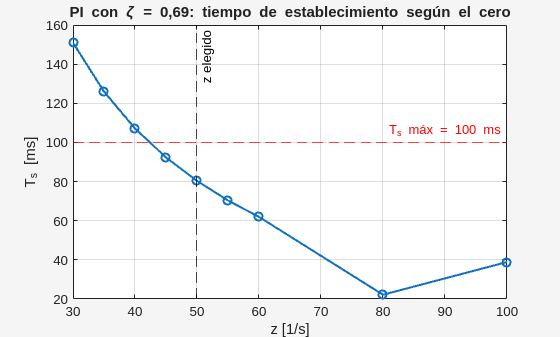

figure
plot(z_prueba, 1e3*Ts_z, 'o-', 'LineWidth', 1.5); hold on
yline(1e3*Ts_max, 'r--', 'T_s máx = 100 ms');
xline(50, 'k--', 'z elegido');
grid on; xlabel('z [1/s]'); ylabel('T_s [ms]')
title('PI con \zeta = 0,69: tiempo de establecimiento según el cero')
guardar("TP2_PI2c_eleccion_z")

z = 50;
zeta_de_kp = @(kp) zeta_par_complejo(roots([a3, a2, 1 + kp, kp*z]));
kp_PI = fzero(@(kp) zeta_de_kp(kp) - zeta_d, [0.5 5])

kp_PI = 1.3589

ki_PI = kp_PI*z

ki_PI = 67.9461

routh_ok   = (ki_PI > 0) && (ki_PI < 312.77*(1 + kp_PI))

routh_ok = logical
   1


polos_PI   = roots([a3, a2, 1 + kp_PI, ki_PI])

polos_PI = 1.0e+02 *

  -1.3842 + 1.4520i
  -1.3842 - 1.4520i
  -0.3592 + 0.0000i


sigma_a_PI = (-100 - 1/tau2 + z)/2

sigma_a_PI = -131.3830

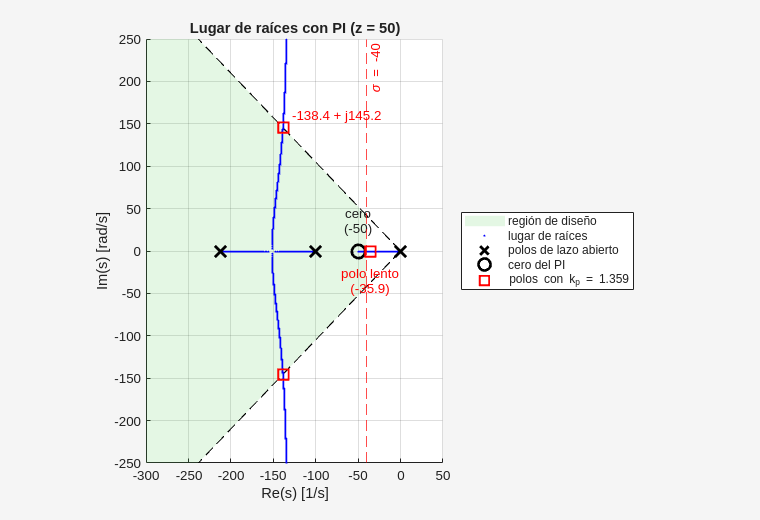

kp_barrido = [linspace(0, 5, 3000), logspace(log10(5), 3, 500)];
raices_lr = zeros(3, numel(kp_barrido));
for j = 1:numel(kp_barrido)
    raices_lr(:, j) = roots([a3, a2, 1 + kp_barrido(j), kp_barrido(j)*z]);
end

figure('Position', [100 100 760 520])
dibujar_region(zeta_min, sigma_min, -300, 250)
h0 = findobj(gca, 'Type', 'Patch');
h1 = plot(real(raices_lr(:)), imag(raices_lr(:)), 'b.', 'MarkerSize', 4);
h2 = plot([0 -100 -1/tau2], [0 0 0], 'kx', 'MarkerSize', 12, 'LineWidth', 2);
h3 = plot(-z, 0, 'ko', 'MarkerSize', 10, 'LineWidth', 2);
h4 = plot(real(polos_PI), imag(polos_PI), 'rs', 'MarkerSize', 10, 'LineWidth', 2);

[~, k]  = max(imag(polos_PI));
p_dom   = polos_PI(k);
p_lento = real(polos_PI(abs(imag(polos_PI)) < 1e-6));
text(real(p_dom) + 10, imag(p_dom) + 15, sprintf('%.1f + j%.1f', real(p_dom), imag(p_dom)), 'Color', 'r')
text(p_lento, -35, sprintf('polo lento\n(%.1f)', p_lento), 'Color', 'r', 'HorizontalAlignment', 'center')
text(-z, 35, sprintf('cero\n(%d)', -z), 'HorizontalAlignment', 'center')

legend([h0 h1 h2 h3 h4], ["región de diseño", "lugar de raíces", "polos de lazo abierto", "cero del PI", "polos con k_p = " + round(kp_PI, 3)], 'Location', 'eastoutside')
title("Lugar de raíces con PI (z = " + z + ")")
guardar("TP2_PI2c_lugar_raices")

%% 2d.
T_PI = feedback(kp_PI*(s + z)/s*G, 1);
t_d  = (0:1e-5:0.15)';
y_PI = step(T_PI, t_d);
info_PI = stepinfo(y_PI, t_d, dcgain(T_PI))

info_PI = struct with fields:
         RiseTime: 0.0314
    TransientTime: 0.0804
     SettlingTime: 0.0804
      SettlingMin: 0.9000
      SettlingMax: 0.9984
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9984
         PeakTime: 0.1500


ess_PI  = 1 - dcgain(T_PI)

ess_PI = 0

wn_dom   = abs(p_dom)

wn_dom = 200.6120

zeta_dom = -real(p_dom)/wn_dom

zeta_dom = 0.6900

T_2do = wn_dom^2/(s^2 + 2*zeta_dom*wn_dom*s + wn_dom^2);
y_2do = step(T_2do, t_d);
info_2do = stepinfo(y_2do, t_d, 1)

info_2do = struct with fields:
         RiseTime: 0.0104
    TransientTime: 0.0299
     SettlingTime: 0.0299
      SettlingMin: 0.9004
      SettlingMax: 1.0500
        Overshoot: 5.0044
       Undershoot: 0
             Peak: 1.0500
         PeakTime: 0.0216


y_P = step(feedback(1.413*G, 1), t_d);

[num_Y, den_Y] = tfdata(T_PI/s, 'v');
[res_Y, polos_Y] = residue(num_Y, den_Y);
A_lento = real(res_Y(abs(polos_Y - p_lento) < 1e-3))

A_lento = -0.3587

Ts_estimado = log(abs(A_lento)/0.02)/abs(p_lento)

Ts_estimado = 0.0804

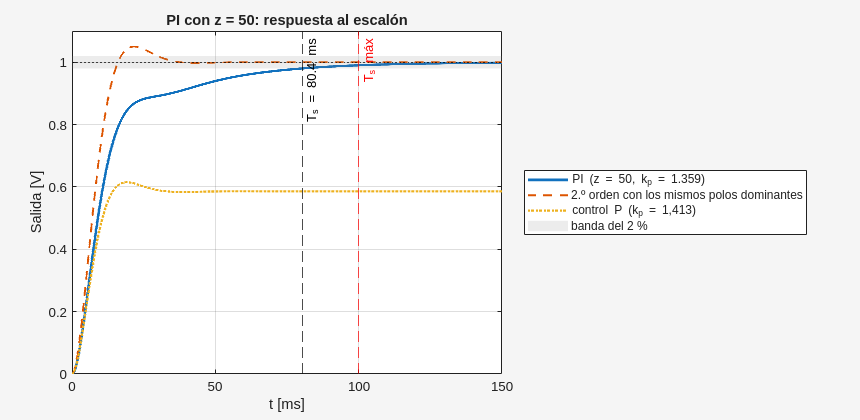

figure('Position', [100 100 860 420])
hPI = plot(t_d*1e3, y_PI, 'LineWidth', 2); hold on
h2  = plot(t_d*1e3, y_2do, '--', 'LineWidth', 1.5);
hP  = plot(t_d*1e3, y_P, ':', 'LineWidth', 1.8);
hb  = patch([0 150 150 0], [0.98 0.98 1.02 1.02], [0.5 0.5 0.5], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
yline(1, 'k:');
xline(1e3*info_PI.SettlingTime, 'k--', "T_s = " + round(1e3*info_PI.SettlingTime, 1) + " ms");
xline(1e3*Ts_max, 'r--', 'T_s máx');
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); ylim([0 1.1])
legend([hPI h2 hP hb], ["PI (z = 50, k_p = " + round(kp_PI, 3) + ")", "2.º orden con los mismos polos dominantes", "control P (k_p = 1,413)", "banda del 2 %"], 'Location', 'eastoutside')
title('PI con z = 50: respuesta al escalón')
guardar("TP2_PI2d_escalon")

%% 3b.
C_PI = 0.1e-6;                       
R_PI2_ideal = 1/(z*C_PI)        

R_PI2_ideal = 2.0000e+05

R_PI1_ideal = R_PI2_ideal/kp_PI   

R_PI1_ideal = 1.4718e+05

R_PI2 = 200e3;                       
R_opciones = [120e3 130e3 150e3 160e3 180e3];
kp_op = R_PI2./R_opciones;
ki_op = 1./(R_opciones*C_PI);
zeta_op = zeros(size(R_opciones));
PO_op = zeros(size(R_opciones));
Ts_op = zeros(size(R_opciones));
t_op = (0:1e-5:0.4)';
for i = 1:numel(R_opciones)
    T_i = feedback((kp_op(i)*s + ki_op(i))/s*G, 1);
    zeta_op(i) = zeta_par_complejo(pole(T_i));
    info_i = stepinfo(step(T_i, t_op), t_op, 1);
    PO_op(i) = info_i.Overshoot;
    Ts_op(i) = info_i.SettlingTime;
end
tabla_RPI1 = table(R_opciones'/1e3, kp_op', ki_op', zeta_op', PO_op', 1e3*Ts_op', 'VariableNames', {'R_PI1_kOhm', 'kp', 'ki', 'zeta_dom', 'PO', 'Ts_ms'})

tabla_RPI1 = 5×6 table
    R_PI1_kOhm      kp        ki      zeta_dom    PO    Ts_ms 
    __________    ______    ______    ________    __    ______

       120        1.6667    83.333    0.63824     0      69.61
       130        1.5385    76.923    0.65851     0     73.613
       150        1.3333    66.667    0.69481     0     81.459
       160          1.25      62.5     0.7111     0     85.329
       180        1.1111    55.556    0.74048     0     93.004


R_PI1  = 150e3;
R_INV1 = 10e3;
R_INV2 = 10e3;                   
kp_c2 = R_PI2/R_PI1

kp_c2 = 1.3333

ki_c2 = 1/(R_PI1*C_PI)

ki_c2 = 66.6667

z_c2  = ki_c2/kp_c2

z_c2 = 50.0000

Gc_c2 = (kp_c2*s + ki_c2)/s;
T_c2  = feedback(Gc_c2*G, 1);
info_c2 = stepinfo(step(T_c2, t_op), t_op, 1)

info_c2 = struct with fields:
         RiseTime: 0.0325
    TransientTime: 0.0815
     SettlingTime: 0.0815
      SettlingMin: 0.9000
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.4000


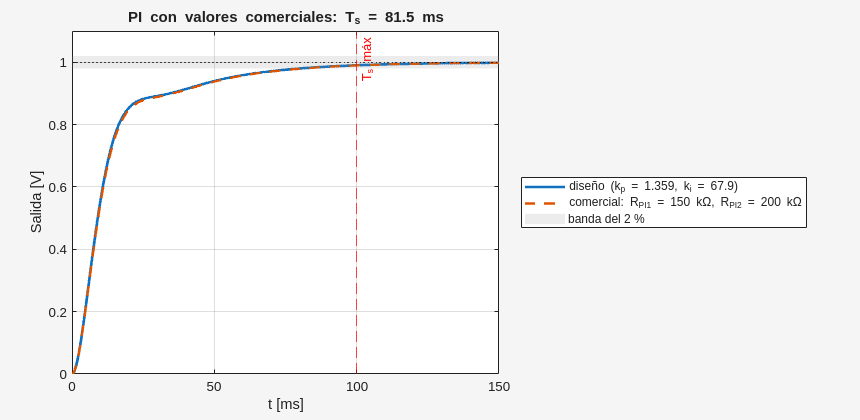

figure('Position', [100 100 860 420])
h1 = plot(t_op*1e3, step(T_PI, t_op), 'LineWidth', 2); hold on
h2 = plot(t_op*1e3, step(T_c2, t_op), '--', 'LineWidth', 1.8);
hb = patch([0 400 400 0], [0.98 0.98 1.02 1.02], [0.5 0.5 0.5], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
yline(1, 'k:');
xline(1e3*Ts_max, 'r--', 'T_s máx');
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 150]); ylim([0 1.1])
legend([h1 h2 hb], ["diseño (k_p = " + round(kp_PI, 3) + ", k_i = " + round(ki_PI, 1) + ")", "comercial: R_{PI1} = 150 k\Omega, R_{PI2} = 200 k\Omega", "banda del 2 %"], 'Location', 'eastoutside')
title("PI con valores comerciales: T_s = " + round(1e3*info_c2.SettlingTime, 1) + " ms")
guardar("TP2_PI3_comercial")

%% 4a y 4b. 
Vin = 1;                  
modelo_PI = 'lazo_PI';
load_system(modelo_PI)
t5  = (0:1e-5:0.4)';
out_PI  = sim(modelo_PI, 'StopTime', '0.4');
y_sim   = leer_senal(out_PI, 'y_sim', t5);
vo1_sim = leer_senal(out_PI, 'vo1_sim', t5);
vpi_sim = leer_senal(out_PI, 'vpi_sim', t5);

y_FT   = step(T_c2, t5);
vpi_FT = step(feedback(Gc_c2, G), t5);  
err_max  = max(abs(y_sim - y_FT))

err_max = 3.7789e-05

info_FT  = stepinfo(y_FT, t5, 1)

info_FT = struct with fields:
         RiseTime: 0.0325
    TransientTime: 0.0815
     SettlingTime: 0.0815
      SettlingMin: 0.9000
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.4000


info_sim = stepinfo(y_sim, t5, y_sim(end))

info_sim = struct with fields:
         RiseTime: 0.0325
    TransientTime: 0.0815
     SettlingTime: 0.0815
      SettlingMin: 0.9000
      SettlingMax: 1.0000
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0000
         PeakTime: 0.4000


ess_sim  = 1 - y_sim(end)

ess_sim = 5.2323e-06

vpi_0 = vpi_sim(find(t5 >= 1e-4, 1))

vpi_0 = 1.3397

[vpi_max, i_max] = max(vpi_sim);
vpi_max

vpi_max = 1.4020

t_vpi_max = t5(i_max)

t_vpi_max = 0.0023

vpi_final = vpi_sim(end)

vpi_final = 1.0000

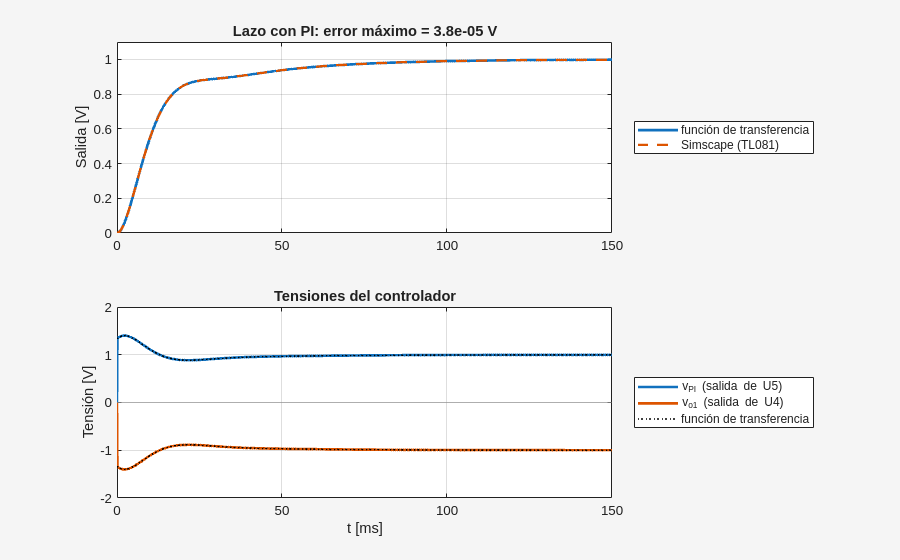

figure('Position', [100 100 900 560])
subplot(2,1,1)
h1 = plot(t5*1e3, y_FT, 'LineWidth', 2); hold on
h2 = plot(t5*1e3, y_sim, '--', 'LineWidth', 1.8);
grid on; ylabel('Salida [V]'); xlim([0 150]); ylim([0 1.1])
legend([h1 h2], ["función de transferencia", "Simscape (TL081)"], 'Location', 'eastoutside')
title("Lazo con PI: error máximo = " + sprintf('%.1e', err_max) + " V")
subplot(2,1,2)
h3 = plot(t5*1e3, vpi_sim, 'LineWidth', 2); hold on
h4 = plot(t5*1e3, vo1_sim, 'LineWidth', 2);
h5 = plot(t5*1e3, vpi_FT, 'k:', 'LineWidth', 1.2);
plot(t5*1e3, -vpi_FT, 'k:', 'LineWidth', 1.2);
yline(0, 'Color', [0.6 0.6 0.6]);
grid on; xlabel('t [ms]'); ylabel('Tensión [V]'); xlim([0 150]); ylim([-2 2])
legend([h3 h4 h5], ["v_{PI} (salida de U5)", "v_{o1} (salida de U4)", "función de transferencia"], 'Location', 'eastoutside')
title('Tensiones del controlador')
guardar("TP2_PI4_simscape")

%% 4c.
A_sat = 8.5/vpi_max                      

A_sat = 6.0627

amplitudes = [5 6.1 7 7.5];
t5 = (0:1e-5:0.4)';
y_lineal = step(T_c2, t5);                
y_norm  = zeros(numel(t5), numel(amplitudes));
vpi_A   = zeros(numel(t5), numel(amplitudes));
sat_ini = nan(size(amplitudes));
sat_fin = nan(size(amplitudes));
PO_A  = zeros(size(amplitudes));
Ts_A  = zeros(size(amplitudes));
dif_A = zeros(size(amplitudes));
for i = 1:numel(amplitudes)
    Vin = amplitudes(i);
    out_i = sim(modelo_PI, 'StopTime', '0.4');
    y_i = leer_senal(out_i, 'y_sim', t5);
    vpi_A(:, i)  = leer_senal(out_i, 'vpi_sim', t5);
    y_norm(:, i) = y_i/Vin;
    saturado = vpi_A(:, i) >= 8.49;
    if any(saturado)
        sat_ini(i) = t5(find(saturado, 1, 'first'));
        sat_fin(i) = t5(find(saturado, 1, 'last'));
    end
    info_i = stepinfo(y_i, t5, y_i(end));
    PO_A(i)  = info_i.Overshoot;
    Ts_A(i)  = info_i.SettlingTime;
    dif_A(i) = max(abs(y_i - Vin*y_lineal));
end
Vin = 1;                                   
tabla_sat = table(amplitudes', max(vpi_A)', 1e3*sat_ini', 1e3*sat_fin', PO_A', 1e3*Ts_A', dif_A', 'VariableNames', {'A_V', 'vPI_max', 'sat_desde_ms', 'sat_hasta_ms', 'PO', 'Ts_ms', 'dif_max_V'})

tabla_sat = 4×7 table
    A_V    vPI_max    sat_desde_ms    sat_hasta_ms    PO    Ts_ms     dif_max_V 
    ___    _______    ____________    ____________    __    ______    __________

      5    7.0101          NaN             NaN        0     81.461    0.00022727
    6.1    8.4999         1.35            3.29        0     81.456     0.0032337
      7    8.4999         0.01            8.76        0     80.978        0.3416
    7.5    8.4999         0.01           11.59        0     80.547        0.6182


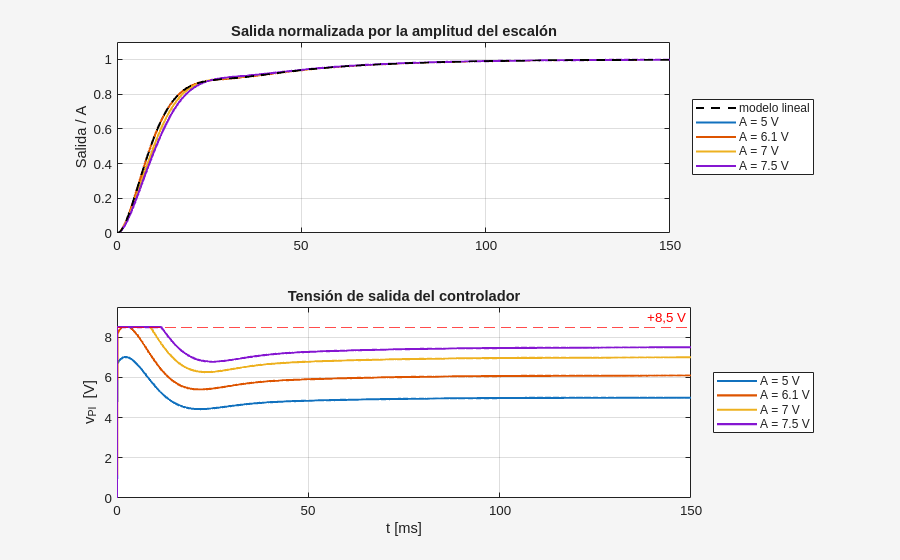

figure('Position', [100 100 900 560])
subplot(2,1,1)
hA = plot(t5*1e3, y_norm, 'LineWidth', 1.6); hold on
hl = plot(t5*1e3, y_lineal, 'k--', 'LineWidth', 1.5);
grid on; ylabel('Salida / A'); xlim([0 150]); ylim([0 1.1])
legend([hl; hA], ["modelo lineal", "A = " + string(amplitudes) + " V"], 'Location', 'eastoutside')
title('Salida normalizada por la amplitud del escalón')
subplot(2,1,2)
hv = plot(t5*1e3, vpi_A, 'LineWidth', 1.6); hold on
yline(8.5, 'r--', '+8,5 V');
grid on; xlabel('t [ms]'); ylabel('v_{PI} [V]'); xlim([0 150]); ylim([0 9.5])
legend(hv, "A = " + string(amplitudes) + " V", 'Location', 'eastoutside')
title('Tensión de salida del controlador')
guardar("TP2_PI4c_saturacion")

%% 5.
Vin = 1;
t_c = (0:1e-5:0.4)';
out_P    = sim(modelo_P, 'StopTime', '0.4');
y_P_sim  = leer_senal(out_P, 'y_sim', t_c);
out_PI   = sim(modelo_PI, 'StopTime', '0.4');
y_PI_sim = leer_senal(out_PI, 'y_sim', t_c);
info_P_sim  = stepinfo(y_P_sim, t_c, y_P_sim(end));
info_PI_sim = stepinfo(y_PI_sim, t_c, y_PI_sim(end));
tabla_final = table(["P (kp = 1,413)"; "PI (kp = 1,333, ki = 66,7)"], [info_P_sim.Overshoot; info_PI_sim.Overshoot], 1e3*[info_P_sim.SettlingTime; info_PI_sim.SettlingTime], [y_P_sim(end); y_PI_sim(end)], [1 - y_P_sim(end); 1 - y_PI_sim(end)], 'VariableNames', {'Controlador', 'PO', 'Ts_ms', 'y_final', 'ess'})

tabla_final = 2×5 table
            Controlador               PO      Ts_ms     y_final       ess    
    ____________________________    ______    ______    _______    __________

    "P (kp = 1,413)"                4.9996    26.458    0.58563       0.41437
    "PI (kp = 1,333, ki = 66,7)"         0     81.46    0.99999    5.2323e-06


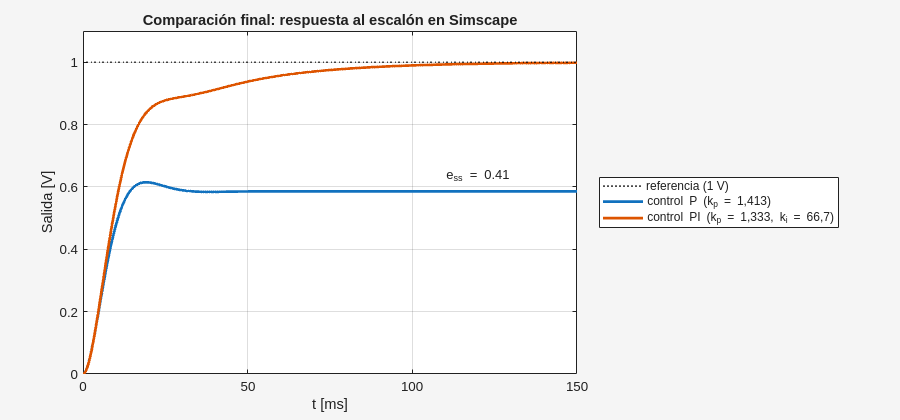

figure('Position', [100 100 900 420])
h1 = plot(t_c*1e3, y_P_sim, 'LineWidth', 2); hold on
h2 = plot(t_c*1e3, y_PI_sim, 'LineWidth', 2);
h3 = yline(1, 'k:', 'LineWidth', 1.2);
text(110, y_P_sim(end) + 0.05, sprintf('e_{ss} = %.2f', 1 - y_P_sim(end)))
grid on; xlabel('t [ms]'); ylabel('Salida [V]'); xlim([0 150]); ylim([0 1.1])
legend([h3 h1 h2], ["referencia (1 V)", "control P (k_p = 1,413)", "control PI (k_p = 1,333, k_i = 66,7)"], 'Location', 'eastoutside')
title('Comparación final: respuesta al escalón en Simscape')
guardar("TP2_5_comparacion")

print('-slazo_P',  '-dpng', '-r300', 'imagenes/TP2_modelo_P.png')
print('-slazo_PI', '-dpng', '-r300', 'imagenes/TP2_modelo_PI.png')

% ---------------------------------------------------------------------
% Funciones auxiliares (en un Live Script tienen que ir al final)
% ---------------------------------------------------------------------
function guardar(nombre)
% Pasa la figura actual a tema claro (fondo blanco) y la guarda en imagenes/
    f = gcf;
    theme(f, "light");
    if ~isfolder("imagenes")
        mkdir("imagenes");
    end
    exportgraphics(f, "imagenes/" + nombre + ".png", "Resolution", 300);
end

function dibujar_region(zeta_min, sigma_min, x_izq, y_max)
% Dibuja la región del plano s donde deben quedar los polos dominantes
    tn = tan(acos(zeta_min));
    hold on
    patch([-sigma_min x_izq x_izq -sigma_min], [sigma_min*tn -x_izq*tn x_izq*tn -sigma_min*tn], [0.3 0.8 0.3], 'FaceAlpha', 0.15, 'EdgeColor', 'none');
    plot([0 x_izq], [0 -x_izq*tn], 'k--', [0 x_izq], [0 x_izq*tn], 'k--');
    xline(-sigma_min, 'r--', '\sigma = -40');
    grid on; axis equal
    xlim([x_izq 50]); ylim([-y_max y_max])
    xlabel('Re(s) [1/s]'); ylabel('Im(s) [rad/s]')
end

function zeta = zeta_par_complejo(raices)
% Amortiguamiento del par de polos complejos. Si todos los polos son reales, devuelve 1.
    complejos = raices(abs(imag(raices)) > 1e-9);
    if isempty(complejos)
        zeta = 1;
    else
        p = complejos(1);
        zeta = -real(p)/abs(p);
    end
end

function v = leer_senal(out, nombre, t)
% Lee una señal guardada con To Workspace (Timeseries) y la pasa a la grilla t
    senal = out.get(nombre);
    [tt, iu] = unique(senal.Time);
    vv = squeeze(senal.Data);
    v = interp1(tt, vv(iu), t);
end